# Assignment 3

### Problem 1

#### **a]**

G= tf(20 , [1 7 10 0])


G =
 
          20
  ------------------
  s^3 + 7 s^2 + 10 s
 
Continuous-time transfer function.



%C_pid=pidTuner(G, 'pid');
Kp= 0.97497; Ki=0.049272; Kd= 1.0284;
C_pid=pid(Kp,Ki,Kd);
T_pid = feedback(C_pid * G, 1);
final_value = dcgain(T_pid);
ess= 1- final_value

ess = 0

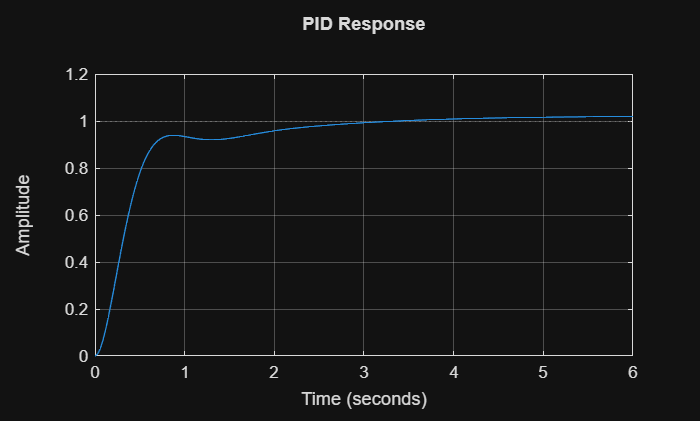

step(T_pid);grid on;title 'PID Response';

%stepinfo(T_pid)

`RiseTime: 0.5485`

`SettlingTime: 7.9452`

`Overshoot: 2.0116, TransientTime: 7.9452`

#### `b]`

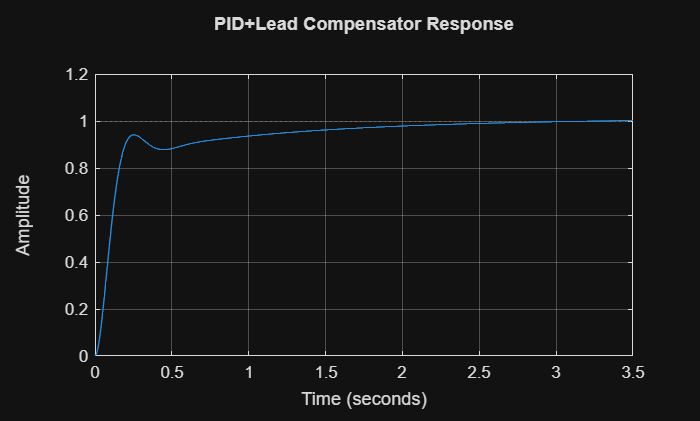

K_c=10;
s=tf('s');
C_lead = K_c * (s + 3)/(s + 15);
C_total= C_lead*C_pid;
T_lead = feedback(C_total * G, 1);
step(T_lead); grid on; title 'PID+Lead Compensator Response';

#### **c]**

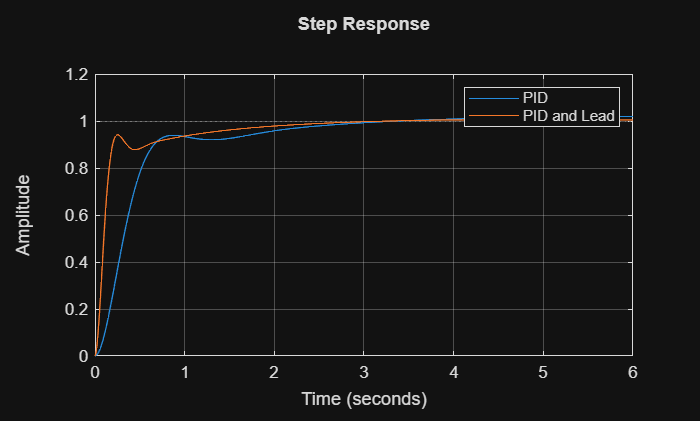

step(T_pid);grid on;hold on;
step(T_lead); grid on; hold off;legend('PID', 'PID and Lead');

%stepinfo(T_lead)

The compensator adds a zero at s = -3 and a pole at s = -15. Because the zero is closer to the origin than the pole (|z| < |p|), the net effect is to shift the root locus of the closed-loop system further to the left in the complex s-plane. Poles further to the left correspond to faster time constants, resulting in a reduced Rise Time and Settling Time.

#### **d]**

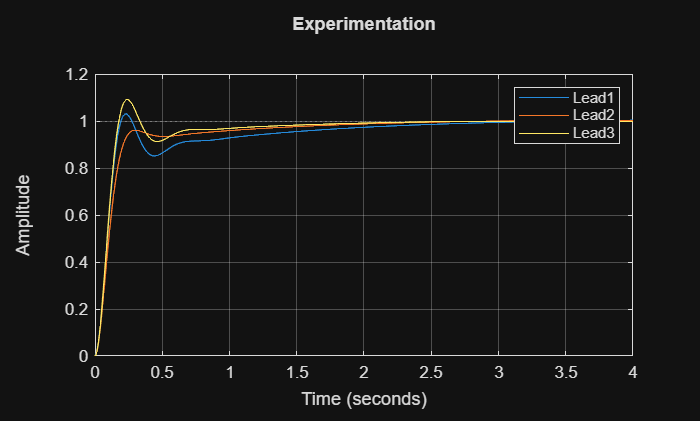

C_lead1=tf([10 20], [1 10]);
C_lead2=tf([10 50], [1 20]);
C_lead3=tf([10 40], [1 12]);
C_total1= C_lead1*C_pid;
C_total2= C_lead2*C_pid;
C_total3= C_lead3*C_pid;
T_lead1 = feedback(C_total1 * G, 1);
T_lead2 = feedback(C_total2 * G, 1);
T_lead3 = feedback(C_total3 * G, 1);
step(T_lead1);grid on;hold on;
step(T_lead2);
step(T_lead3);hold off;
legend('Lead1', 'Lead2', 'Lead3');title 'Experimentation';

Zeros closer to the origin (smaller z) have a stronger effect in reducing the transient response at lower frequencies but can increase overshoot if not balanced by the pole. Poles further left (larger p) extend the bandwidth of the system reducing the rise and settling time, making it faster, but this also makes the system more susceptible to high-frequency noise. The separation distance between the zero and the pole determines the amount of maximum phase lead added. A larger separation generally provides more phase lead but requires higher gain to maintain low-frequency magnitude.

### Problem 2

#### **a] **

s = tf('s');
G = 50 / ((s + 1) * (s + 3) * (s + 8));
Kp=2; C_p=pid(Kp);
T_p=feedback(C_p*G,1);
e_ss_p = 1 - dcgain(T_p)

e_ss_p = 0.1935

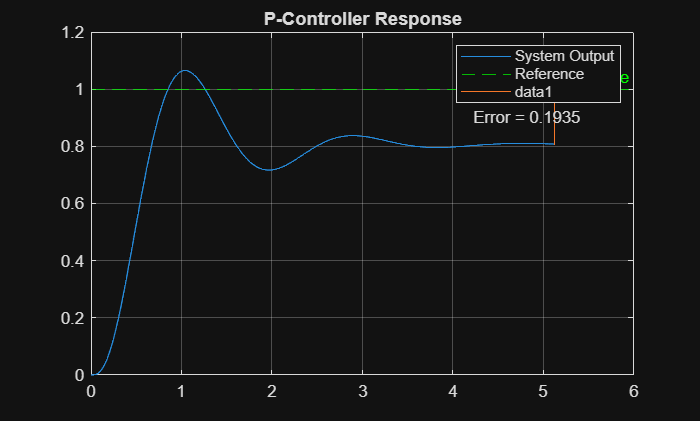

figure;
[y, t] = step(T_p);r=1; y_final = y(end);
plot(t, y); 
grid on;
yline(1, 'g--' ,'Reference');title ('P-Controller Response');
legend('System Output', 'Reference');
x_final=t(end);
line([x_final, x_final], [y_final, r]);
text(x_final - 1, (r + y_final)/2, sprintf('  Error = %.4f', e_ss_p));

#### **b]**

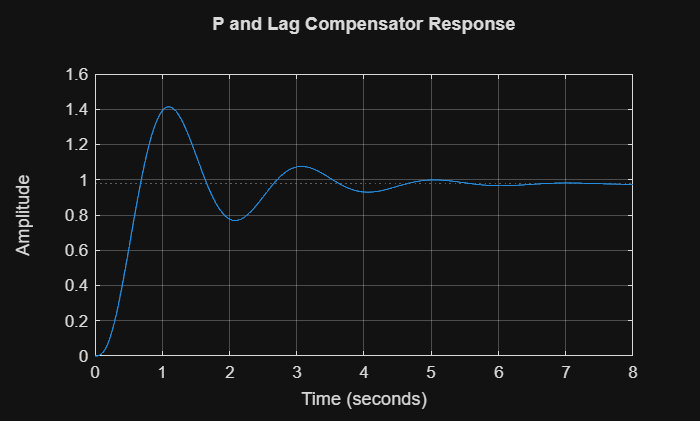

C_lag=(s+1)/(s+0.1);
C2=C_lag*C_p;
T_lag=feedback(C2*G,1);
step(T_lag);grid on; 
title('P and Lag Compensator Response');

At steady state, the compensator contributes a gain of z/p = 1/0.1 = 10 which significantly reduces the error as it is roughly inversely proportional to the gain. The final value is much closer to 1 than P controller, the error is less than 0.03 compared to 0.1935. But the addition of a pole much closer to the origin significantly increases the overshoot.

#### **c]**

% compared the errors in above answer
e_ss_lag = 1 - dcgain(T_lag)

e_ss_lag = 0.0234

%stepinfo(T_p)

SettlingTime: 3.2198

%stepinfo(T_lag)
%err = ((e_ss_p - e_ss_lag) / e_ss_p) * 100

SettlingTime: 5.2126

The Lag Compensator introduces a high DC gain in the function which significantly reduces the error as it is roughly inversely proportional to the gain. By placing the pole near to the origin we increase the z/p ratio which adds to the DC gain.

#### **d]**

Does settling time increase?  Yes

Is the response slower? Yes

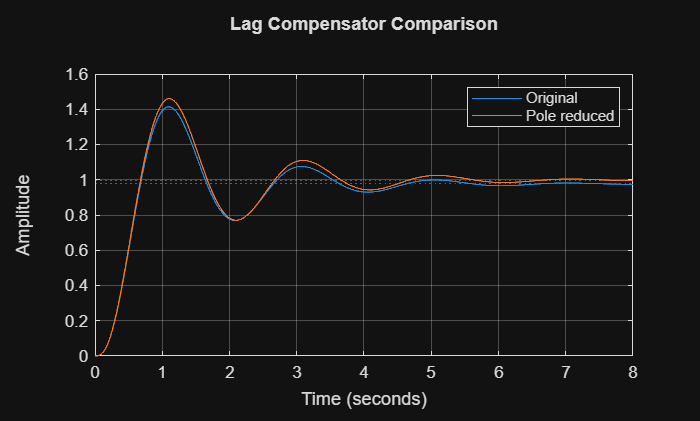

C_lag2=(s+1)/(s+0.01);
C3=C_lag2*C_p;
T_lag2=feedback(C3*G,1);
step(T_lag);grid on;hold on;
step(T_lag2);hold off;
title('Lag Compensator Comparison');
legend('Original','Pole reduced');

%stepinfo(T_lag2)

The Rise time has not changed that is the the rise speed is the same but the settling time has changed (increased) which indicates the settling speed has decreased. The accuracy has increased significantly but the speed had to be compromised.

### Problem 3

#### a]

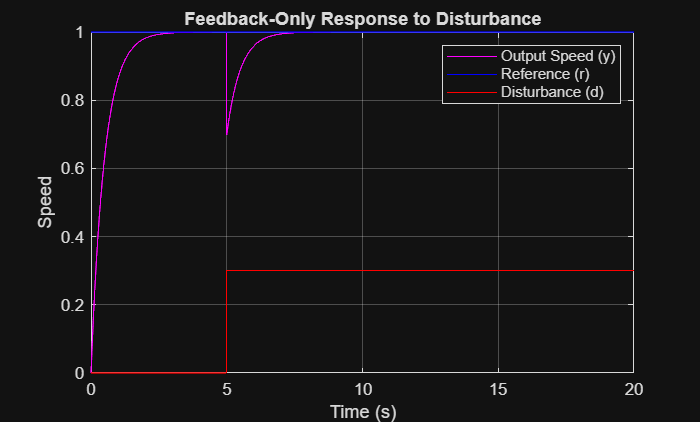

s= tf('s');
G=1/(s+0.5);
C_pi=pid(2,1);
T_ref = feedback(C_pi * G, 1);
t = 0:0.01:20;
r = ones(size(t));
d = zeros(size(t));
d(t >= 5) = 0.3;
% 3. Closed-Loop Transfer Functions
% Deriving the transfer functions based on y = G*u - d
% and u = C_pi*(r - y)
% Algebra: y = G*C_pi*(r - y) - d
%          y(1 + G*C_pi) = G*C_pi*r - d
%          y = [G*C_pi / (1 + G*C_pi)] * r + [-1 / (1 + G*C_pi)] * d
S_dist = feedback(1, G * C_pi);   % Sensitivity function
T_dist = -S_dist;
y_ref_response = lsim(T_ref, r, t);    % Response to reference
y_dist_response = lsim( T_dist , d, t);   % Response to disturbance
y_total = y_ref_response + y_dist_response;
err = r' - y_total;

%Plotting
plot(t, y_total, 'm'); hold on;
plot(t, r,'b');
plot(t, d,'r'); % Show disturbance for context
title('Feedback-Only Response to Disturbance');
xlabel('Time (s)');
ylabel('Speed');
legend('Output Speed (y)', 'Reference (r)', 'Disturbance (d)');
grid on;hold off;

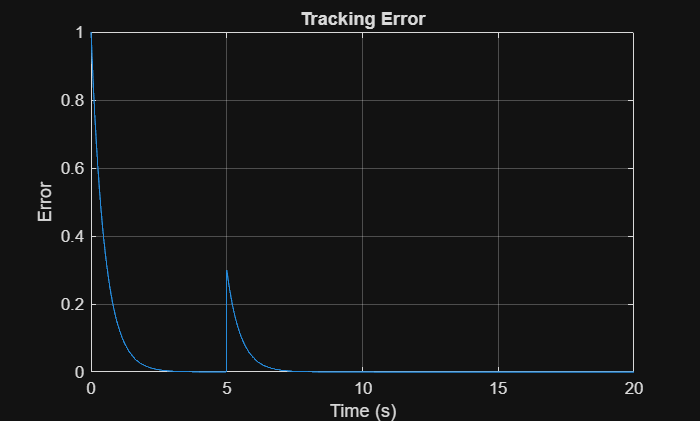

plot(t, err);
title('Tracking Error');
xlabel('Time (s)');
ylabel('Error');
grid on;

d_indices = find(t >= 5);
err_after_d = abs(err(d_indices));
[max_err, idx_max] = max(err_after_d);
time_of_max = t(d_indices(idx_max));
% Recovery Time (Time to return to within 5% of reference after disturbance)
tolerance = 0.05;

violation_idx = find(err_after_d > tolerance);

if ~isempty(violation_idx)
    last_violation_idx = violation_idx(end);
    recovery_timestamp = t(d_indices(last_violation_idx));
    recovery_duration = recovery_timestamp - 5; % Duration from disturbance start
else
    recovery_duration = 0;
end
%max_err
%recovery_duration

Max Error =` 0.3000`

Recovery Time` = 0.8900 s`

#### `b]`

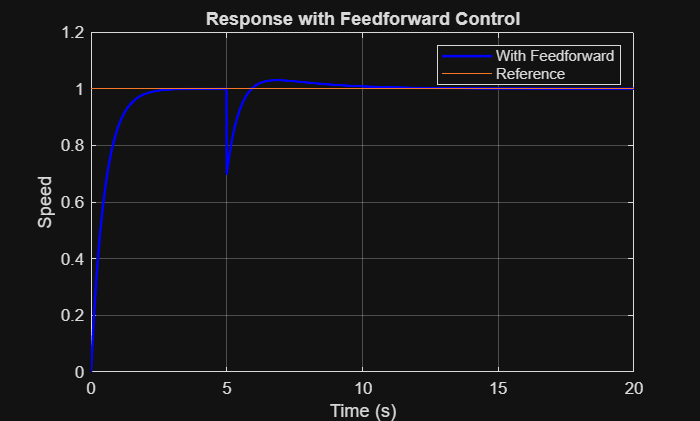

K_ff=1/dcgain(G);
u_ff = K_ff * d;
% C. Feedforward Response
% Transfer function from Control Input (u) to Output (y)
T_in_to_out = feedback(G, C_pi);

% Simulate effect of u_ff signal
y_ff_response = lsim(T_in_to_out, u_ff, t);

% 4. Total Output with Feedforward
y_total_ff = y_ref_response + y_dist_response + y_ff_response;

% Calculate Error
err_ff = r - y_total_ff;

plot(t, y_total_ff, 'b', 'LineWidth', 1.5); hold on;
plot(t, r);
title('Response with Feedforward Control');
xlabel('Time (s)');
ylabel('Speed');
legend('With Feedforward', 'Reference');
grid on;hold off;

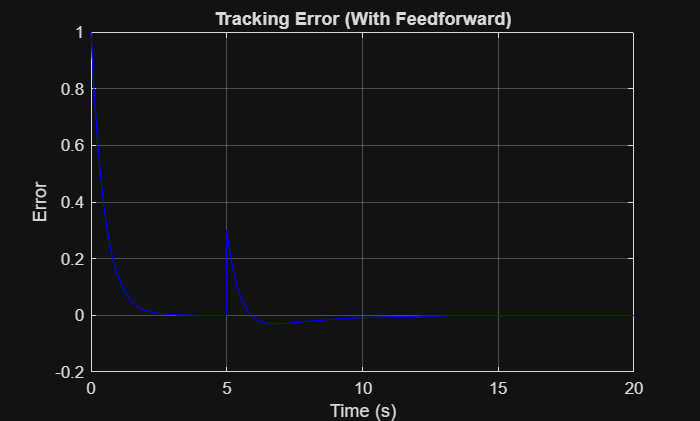

plot(t, err_ff, 'b');
title('Tracking Error (With Feedforward)');
xlabel('Time (s)');
ylabel('Error');
grid on;

#### c]

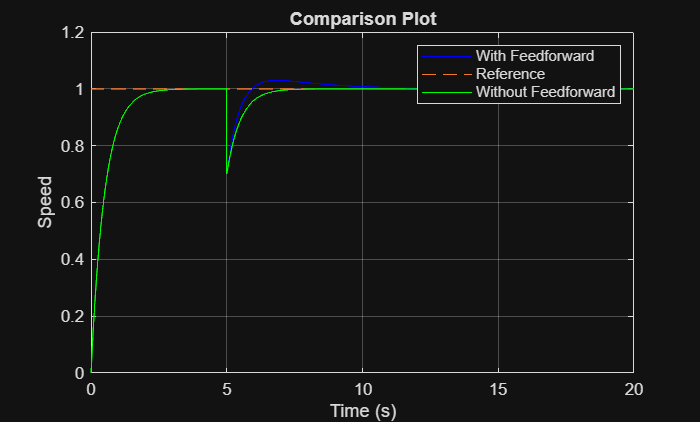

plot(t, y_total_ff, 'b'); hold on;
plot(t, r, '--');
% Plot the 'Without Feedforward' case for immediate visual comparison
plot(t, y_total, 'g'); 
title('Comparison Plot');
xlabel('Time (s)');
ylabel('Speed');
legend('With Feedforward', 'Reference', 'Without Feedforward');
grid on;hold off;

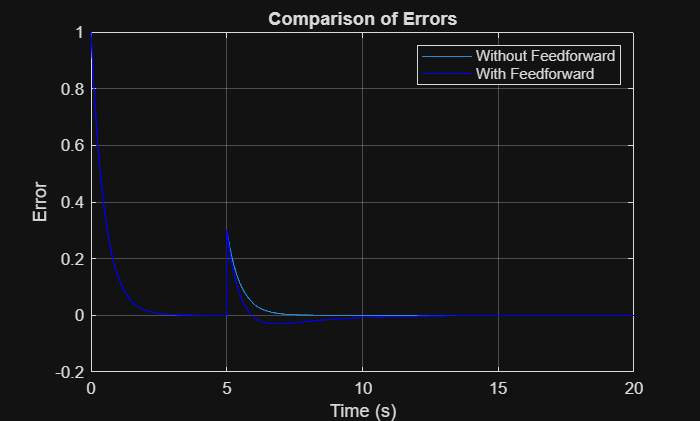

plot(t, err);
title('Comparison of Errors');
xlabel('Time (s)');
ylabel('Error');
grid on;hold on;

plot(t, err_ff, 'b');
xlabel('Time (s)');
ylabel('Error');
grid on;hold off;
legend('Without Feedforward','With Feedforward');

err_ff_after_d = abs(err_ff(d_indices));
[max_err_ff, idx_max_ff] = max(err_ff_after_d);
time_of_max = t(d_indices(idx_max_ff));
% Recovery Time (Time to return to within 5% of reference after disturbance)
tolerance = 0.05;
ff_violation_idx = find(err_ff_after_d > tolerance);

if ~isempty(violation_idx)
    ff_last_violation_idx = ff_violation_idx(end);
    ff_recovery_timestamp = t(d_indices(ff_last_violation_idx));
    ff_recovery_duration = ff_recovery_timestamp - 5; % Duration from disturbance start
else
    ff_recovery_duration = 0;
end

%max_err_ff
%ff_recovery_duration
%sse_fb=err(end)
%sse_ff=err_ff(end)

`Max errorff = 0.3000`

`Recovery Timeff = 0.5800 sec`

Feedforward control is proactive. It measures (or predicts) the disturbance d and immediately calculates the precise input u_ff required to counteract it.

#### d]

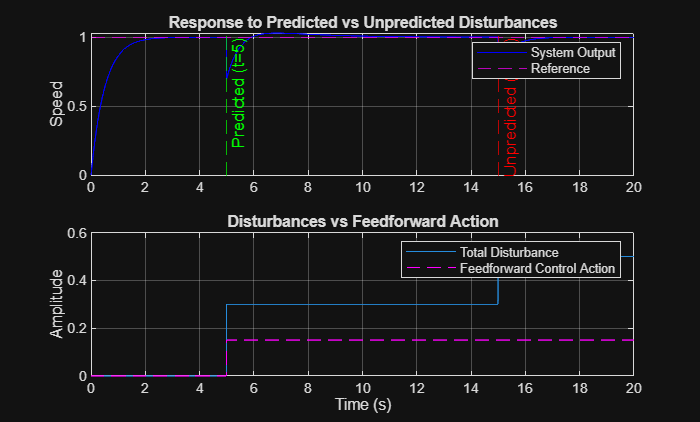

d_unpre = zeros(size(t));
d_unpre(t >= 15) = 0.2;
d_total = d + d_unpre;
% Simulate the total output response with the new disturbance
y_total_dist = lsim( T_dist, d_total, t);
y_final = y_ref_response + y_total_dist + y_ff_response;

subplot(2,1,1);
plot(t, y_final, 'b'); hold on;
yline(1,'m--'); % Reference
xline(5, 'g--', 'Label', 'Predicted (t=5)');
xline(15, 'r--', 'Label', 'Unpredicted (t=15)');
title('Response to Predicted vs Unpredicted Disturbances');
ylabel('Speed');
legend('System Output', 'Reference');
grid on;hold off;

subplot(2,1,2);
plot(t, d_total); hold on;
plot(t, u_ff, 'm--');
title('Disturbances vs Feedforward Action');
xlabel('Time (s)');
ylabel('Amplitude');
legend('Total Disturbance', 'Feedforward Control Action');
grid on;hold off;

idx_event1 = find(t >= 5 & t < 15);
idx_event2 = find(t >= 15);

error_signal = r' - y_final;
%max_err_1 = max(abs(error_signal(idx_event1)))
%max_err_2 = max(abs(error_signal(idx_event2)))

max_err_1 = 0.2971

max_err_2 = 0.1973

At t=5s (Predicted Disturbance)

The output has a very small deviation. The Feedforward controller "knew" this was coming and applied the counter-force (u_ff) at the exact same moment. The disturbance was cancelled before it could create a significant error. Thus feedforward is Proactive Control.

At t=15s (Unpredicted Disturbance) 

There is a sharp dip in speed, followed by a slow recovery. The Feedforward controller did not know about this event, so u_ff did not change. The system had to rely entirely on the Feedback (PI) controller. The feedback controller is Reactive it had to wait for the speed to drop (creating an error) before the Integral term could ramp up to fix it. Thus feedback is Reactive Control. 

### Problem 4

#### a]

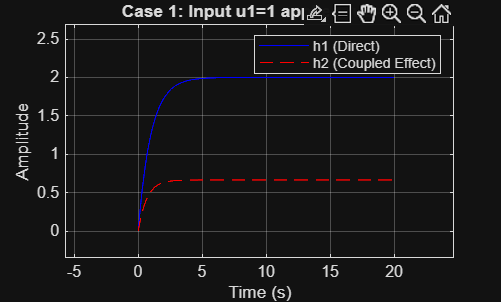

%Open-Loop MIMO Analysis

G11 = tf (2, [1 1]); % Effect of u1 on h1
G12 = tf (0.5 , [1 2]); % Effect of u2 on h1 ( coupling !)
G21 = tf (1, [1 1.5]) ; % Effect of u1 on h2 ( coupling !)
G22 = tf (3, [1 1]);
% 2. Create MIMO System Matrix
% Row 1 is Output 1 (h1), Row 2 is Output 2 (h2)
G = [G11, G12; G21, G22]; % 2x2 MIMO system
t = 0:0.01:20;

% Case 1: Apply Input 1 only (u1=1, u2=0)
u1 = [ones(size(t)); zeros(size(t))]; % Input vector [u1; u2]
y_case1 = lsim(G, u1, t);

% Case 2: Apply Input 2 only (u1=0, u2=1)
u2 = [zeros(size(t)); ones(size(t))]; % Input vector [u1; u2]
y_case2 = lsim(G, u2, t);

% Plotting specific cases to see coupling
plot(t, y_case1(:,1), 'b',t, y_case1(:,2), 'r--');
title('Case 1: Input u1=1 applied (u2=0)');
legend('h1 (Direct)', 'h2 (Coupled Effect)');
xlabel('Time (s)');ylabel('Amplitude'); grid on;

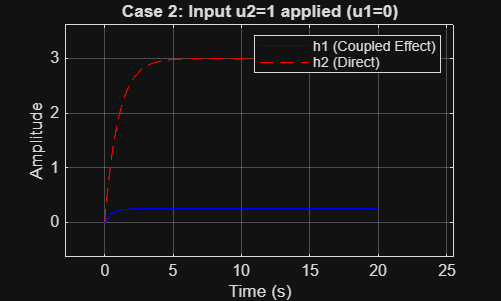

plot(t, y_case2(:,1), 'b',t, y_case2(:,2), 'r--');
title('Case 2: Input u2=1 applied (u1=0)');
legend('h1 (Coupled Effect)', 'h2 (Direct)');
xlabel('Time (s)');ylabel('Amplitude'); grid on;

Changing one input (u_1) affects both outputs because the system dynamics are physically interconnected. You cannot change the level of Tank 1 without affecting or creating a disturbance in Tank 2. If we apply a step input to Input 1 only (u_1 = 1, u_2 = 0), the system equations expand to:

Output 1 (h_1)**:** H_1(s) = 2/(s+1). This is the main effect. The level h_1 will rise to a steady-state value of 2.

Output 2 (h_2): H_2(s) =1/(s+1.5). This is the cross-coupling effect. The level h_2 will rise to a steady-state value of 1/1.5 approx 0.67, solely because of the interaction term G_21.

#### b]

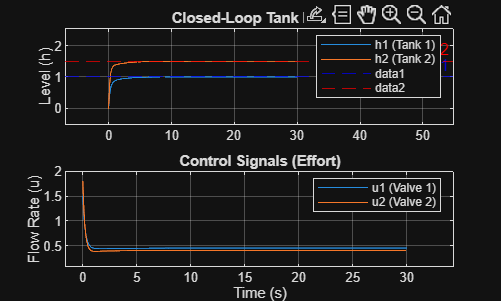

% Define Decentralized Controllers
% Controller 1 for Loop 1
Kp1 = 1.5; Ki1 = 0.8;
C1 = pid(Kp1,Ki1);

% Controller 2 for Loop 2
Kp2 = 1.2; Ki2 = 0.6;
C2 = pid(Kp2,Ki2);

% Creating MIMO Controller Matrix C(s)
C = [C1, 0; 0, C2];

% Creating Closed-Loop Systems
% T = (I + GC)^-1 * GC
T_sys = feedback(G * C, eye(2));

% System for Control Signals (Reference -> Control Input)
T_u = feedback(C, G); 

% 4. Simulation Setup
t = 0:0.01:30;

% Defining References (Step inputs)
r1_val = 1.0;
r2_val = 1.5;
r1 = r1_val * ones(size(t));
r2 = r2_val * ones(size(t));
R = [r1(:), r2(:)]; % Input matrix [r1, r2]

% 5. Simulate Responses
[y, t_out] = lsim(T_sys, R, t); % Outputs (h1, h2)
[u, ~]     = lsim(T_u, R, t);   % Control Signals (u1, u2)

%Tank Levels (Outputs)
subplot(2,1,1);
plot(t, y(:,1)); hold on;
plot(t, y(:,2));
legend('h1 (Tank 1)', 'h2 (Tank 2)');hold off;
yline(r1_val, 'b--', 'Ref 1');
yline(r2_val, 'r--', 'Ref 2');
title('Closed-Loop Tank Levels');
ylabel('Level (h)');

grid on;

%Control Signals (Inputs)
subplot(2,1,2);
plot(t, u(:,1)); hold on;
plot(t, u(:,2));hold off;
title('Control Signals (Effort)');
xlabel('Time (s)');
ylabel('Flow Rate (u)');
legend('u1 (Valve 1)', 'u2 (Valve 2)');
grid on;

%fprintf('Target h1: %.2f | Final h1: %.4f\n', r1_val, y(end,1));
%fprintf('Target h2: %.2f | Final h2: %.4f\n', r2_val, y(end,2));

Target h1: 1.00 | Final h1: 1.0000

Target h2: 1.50 | Final h2: 1.5000

#### c]

1 Yes. As observed in the open-loop analysis, any change in flow u_1 (intended to fix h_1) immediately disturbs h_2.In the plots, we see that even as h_1 approaches its target smoothly, h_2 follows a slower settling process. This is because Controller 2 is constantly fighting the overflow coming from Tank 1.

2 Yes, the outputs definitely interfere with each other. This phenomenon is known as coupling or interaction, and it is the defining characteristic that makes Multi-Input Multi-Output (MIMO) systems challenging to control.

3 Oscillation: This is caused by the Cycle of Interaction

Controller 1 changes u_1 which Disturbs h_2.

Controller 2 reacts by changing u_2 which Disturbs h_1.

Controller 1 must react again.

Settling Time**:** This fighting behavior results in longer settling times compared to isolated loops.

%stepinfo(y(:,1), t, r1_val)
%stepinfo(y(:,2), t, r2_val)
%y(end,1)
%y(end,2)

#### d]

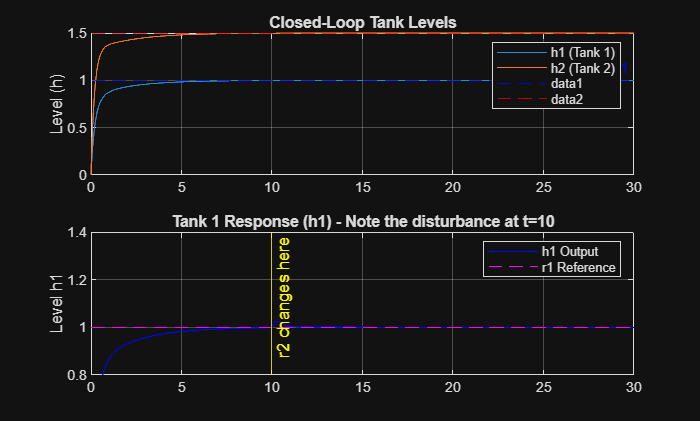

% r1 remains constant at 1.0
r1_seq = ones(size(t));

% r2 starts at 1.0, then steps up to 1.5 at t=10s
r2_seq = ones(size(t));
r2_seq(t >= 10) = 1.5;

% Creating Input Matrix [r1, r2]
R_seq = [r1_seq', r2_seq'];

% 3. Simulating System Response
[y_seq, t_out] = lsim(T_sys, R_seq, t);

% Plotting Tank 1 (h1) - The Victim of interaction
plot(t, y_seq(:,1), 'b'); hold on;
plot(t, r1_seq, 'm--');hold off;
xline(10, 'y-', 'Label', 'r2 changes here');
title('Tank 1 Response (h1) - Note the disturbance at t=10');
ylabel('Level h1');
legend('h1 Output', 'r1 Reference');
ylim([0.8 1.4]); % Zoom in to see the bump
grid on;

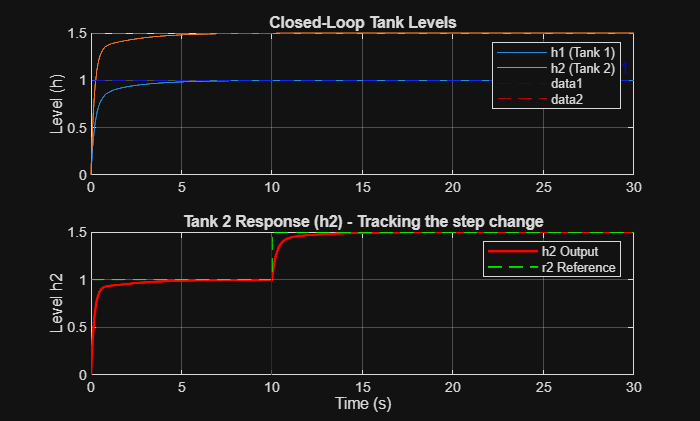

--- Task 4(d) Observation ---


At t=10s, r2 changes. Controller 2 adjusts Valve 2.


Observe the deviation in h1 at t=10s despite r1 being constant.


% Plotting Tank 2 (h2) - The Source of interaction
plot(t, y_seq(:,2), 'r', 'LineWidth', 1.5); hold on;
plot(t, r2_seq, 'g--', 'LineWidth', 1);
xline(10, 'b-');
title('Tank 2 Response (h2) - Tracking the step change');
ylabel('Level h2');
legend('h2 Output', 'r2 Reference');
xlabel('Time (s)');
grid on;hold off;

2 We can see a disturbance in the h1 output at t=10s even though r1 is constant suggesting r2 influenced the disturbance in the r1.

2 The plot demonstrates that Input-Output Decoupling is impossible with simple decentralized control in MIMO system.

At t=10s, you will see a distinct "bump" or deviation in the blue line in tank 1.Reason: When the setpoint for Tank 2 changed, Controller 2 opened Valve 2. Because of the physical coupling (G_12), this action disturbed Tank 1. Controller 1 then had to "wake up" and fight this disturbance to bring the level back to 1.0. In SISO systems, you only fight external disturbances. In MIMO systems, the control loops fight each other, creating internal disturbances that can lead to instability or poor performance.

3 Decoupling Network: We can insert a Decoupler block D(s) before the plant. This block will mathematically cancels out the cross-coupling terms (e.g., subtracting a portion of u1 from u2) so that the plant looks diagonal to the controllers.

Centralized Control (MIMO Control): Instead of two separate PIs, use a centralized strategy like LQR (Linear Quadratic Regulator) or MPC (Model Predictive Control). These algorithms consider the entire matrix G(s) at once and optimize all inputs simultaneously, naturally handling the interactions.

###  Summary Questions

#### 1] 

You choose a **Lead Compensator** when you need to improve transient speed (rise time) while maintaining or improving stability (phase margin). Simply increasing the PID gain (K_p) speeds up the system but degrades stability (increases overshoot/oscillations).

#### 2]

Advantage: It functions like a PI controller, significantly reducing steady-state error by boosting low-frequency gain.

Limitation: The pole near the origin creates a long tail in the transient response, which increases the settling time.

#### 3]

Feedforward is "proactive" because it measures the disturbance and calculates the correction *before* the output is affected.

Feedback is "reactive" because it must wait for an error to appear in the output before it generates a correction.

#### 4] 

MIMO systems are more difficult due to Cross-Coupling. Changing one input affects multiple outputs, causing independent controllers to interfere (fight) with each other, leading to complex oscillation modes that don't exist in SISO systems.